# Atividade 05_06

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Script

g = imread('flowervaseg.png');
%Imfilter retorna imagem da mesma clase da
%de entrada. Se g fosse uint8 o imfilter
%truncaria os valores de saída e a
%visualização da convolução
%seria comprometida. Por isso:
gd = im2double(g);
h = fspecial('laplacian', 0);
gdL = imfilter(gd, h, 'replicate');
gdLs = gd - gdL;
gdLsu = im2uint8(gdLs); %trunca
gdLn = mat2gray(gdL);

## Laplaciano direto e Laplaciano invertido

Obetenha a imagem flowervaseg.png realçada utilizando a máscara do Laplaciano direto (elemento central positivo). O resultado deve ser similar ao do exemplo acima, que foi obtido usando o Laplaciano invertido (elemento central negativo).

img = imread("flowervaseg.png");

imgDouble = im2double(img);
kernel = fspecial("laplacian", 0) * -1

kernel =      0    -1     0
    -1     4    -1
     0    -1     0


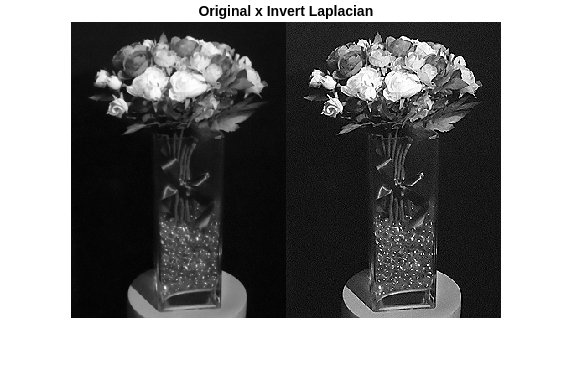

laplacian = imfilter(imgDouble, kernel, "replicate");
processedImage = im2uint8(imgDouble + laplacian);

laplacianFilterAsImg = mat2gray(laplacian);

figure, imshowpair(img, gdLsu, "montage")
title("Original x Invert Laplacian")

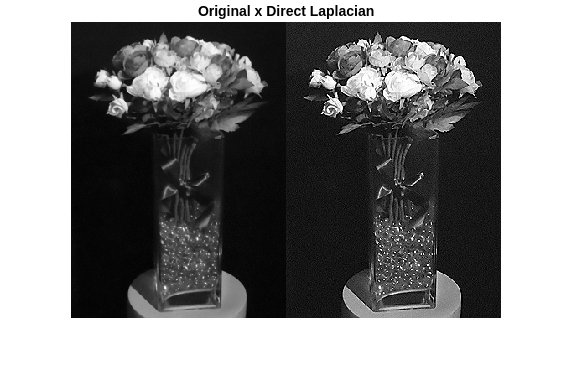


figure, imshowpair(img, processedImage, "montage")
title("Original x Direct Laplacian")

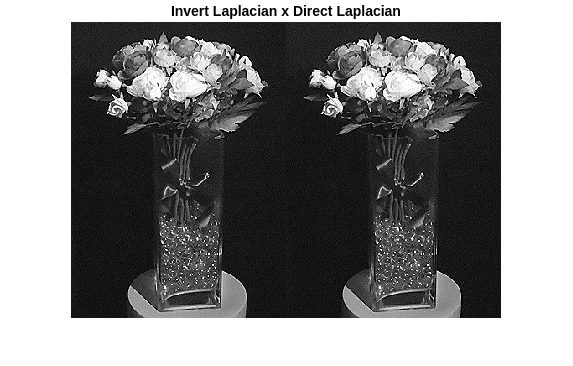



figure, imshowpair(gdLsu, processedImage, "montage")
title("Invert Laplacian x Direct Laplacian")

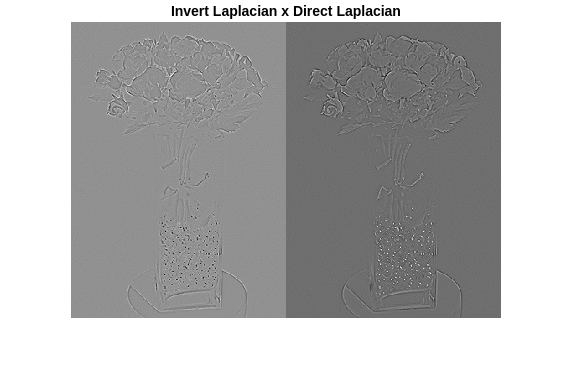


figure, imshowpair(gdLn, laplacianFilterAsImg, "montage")
title("Invert Laplacian x Direct Laplacian")